k = 3;
initcond = 0.5;
timeint = [0 10];
TOL = 10^(-5);
disp('Estimated global error = ')

Estimated global error = 


disp(TOL * exp(k*timeint(2)))

   1.0686e+08



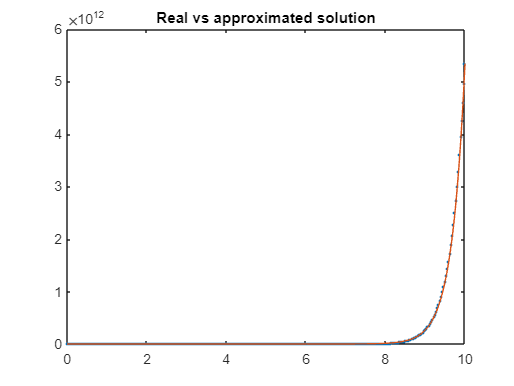


opts = odeset('reltol',TOL,'abstol',TOL);


%Ode45
[t,Y] = ode45(@(t,y) f(t,y,k),timeint,initcond,opts);

figure
plot(t,Y,'.')
hold on
plot(t,initcond*exp(k*t))
title('Real vs approximated solution')

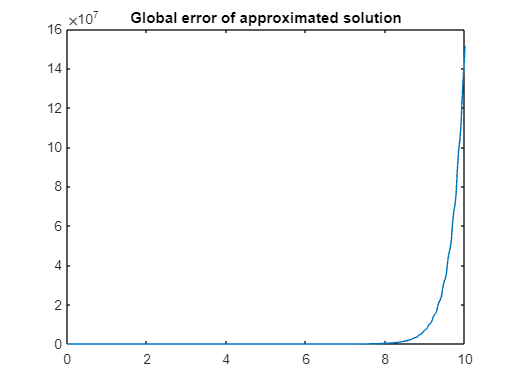


figure
plot(t,abs(Y-initcond*exp(k*t)))
title('Global error of approximated solution')

disp('Error at last point = ')

Error at last point = 


disp(abs(Y(end)-initcond*exp(k*t(end))))

   1.5124e+08






%ode113
disp('----------------------------------')

----------------------------------


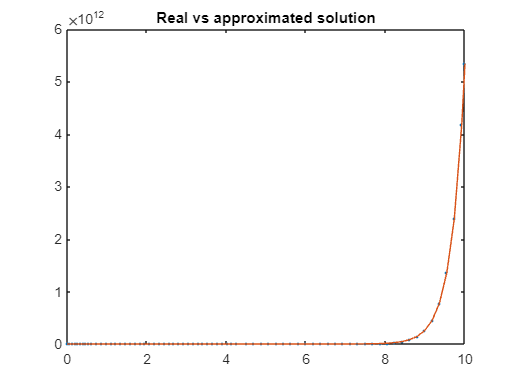

[t2,Z] = ode113(@(t,y) f(t,y,k),timeint,initcond,opts);

figure
plot(t2,Z,'.')
hold on
plot(t2,initcond*exp(k*t2))
title('Real vs approximated solution')

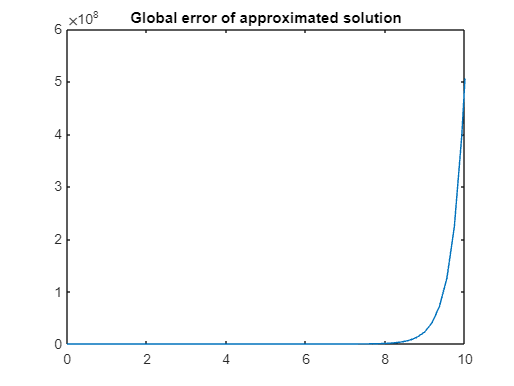


figure
plot(t2,abs(Z-initcond*exp(k*t2)))
title('Global error of approximated solution')

disp('Error at last point = ')

Error at last point = 


disp(abs(Z(end)-initcond*exp(k*t2(end))))

   5.0589e+08



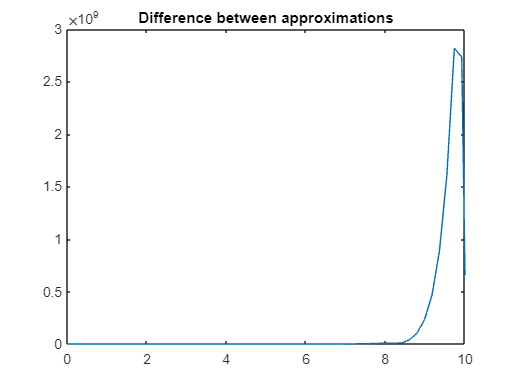



%Comparison
figure
plot(t2,interp1(t,Y,t2)-interp1(t2,Z,t2))
title('Difference between approximations')

disp('Difference at last point = ')

Difference at last point = 


disp(abs(Z(end)-Y(end)))

   6.5713e+08



function z = f(t,y,k)
    z = k*y;
end